Voltage vs Time

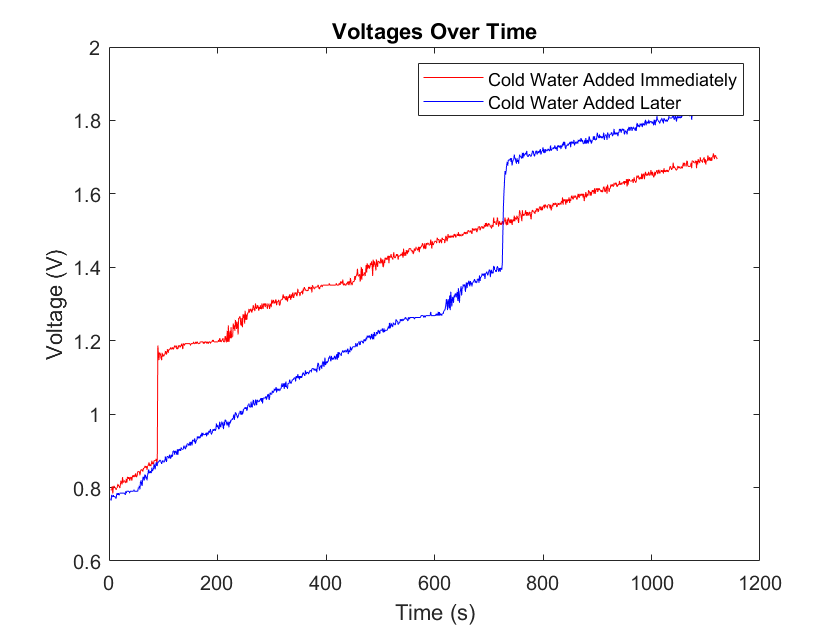

% Plot Voltage Graph
clf;
figure(1)
data = csvread('lab_1_data_results.csv',4);
cup_1_time = data((1:1119),1);
cup_1_voltage = data((1:1119),2);
cup_2_time = data((1:1119),3);
cup_2_voltage = data((1:1119),4);
plot(cup_1_time,cup_1_voltage,'r',cup_2_time,cup_2_voltage,'b')
legend('Cold Water Added Immediately','Cold Water Added Later')
xlabel('Time (s)'), ylabel('Voltage (V)')
title('Voltages Over Time')

Calculate the resistor2 (thermistor)

% Calculate Resistance of the Thermistor
clf;
figure(2)
voltage_in = 5; % Volts
%thermistor_resistance = cup_1_voltage*1000 ./ (voltage_in - cup_1_voltage);
thermistor_resistance_cup_1 = cup_1_voltage*1000 ./ (voltage_in - 1);
thermistor_resistance_cup_2 = cup_2_voltage*1000 ./ (voltage_in - 1);

Calculate the Temperatures and Graph it

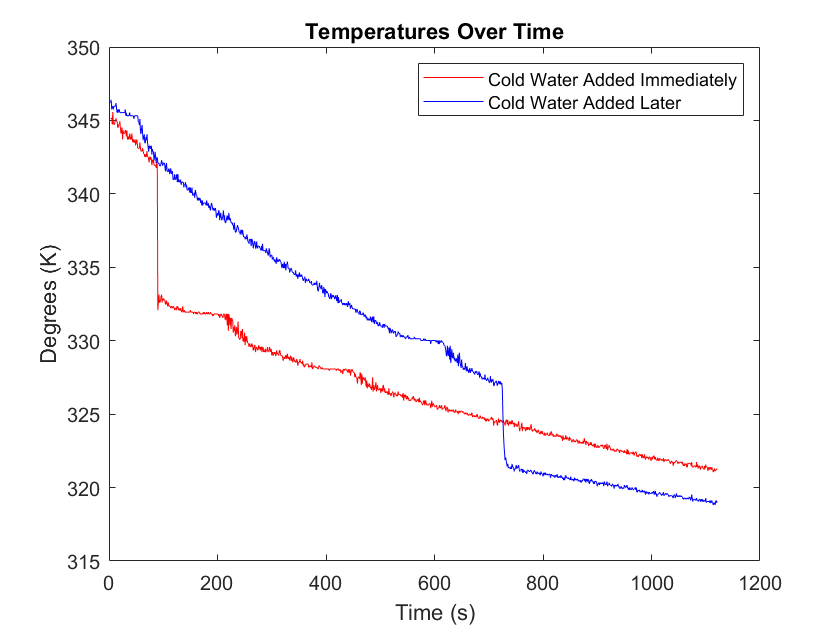

% Calculate Temperature
% temperature = 1./(((log(thermistor_resistance/350))/3528) + (1/298));
cup_1_temperature = 3528 ./ (log(thermistor_resistance_cup_1)-log(1000)+3528/298);
cup_2_temperature = 3528 ./ (log(thermistor_resistance_cup_2)-log(1000)+3528/298);

clf;
plot(cup_1_time,cup_1_temperature, 'r', cup_2_time, cup_2_temperature, 'b')
legend('Cold Water Added Immediately','Cold Water Added Later')
xlabel('Time (s)'), ylabel('Degrees (K)')
title('Temperatures Over Time')

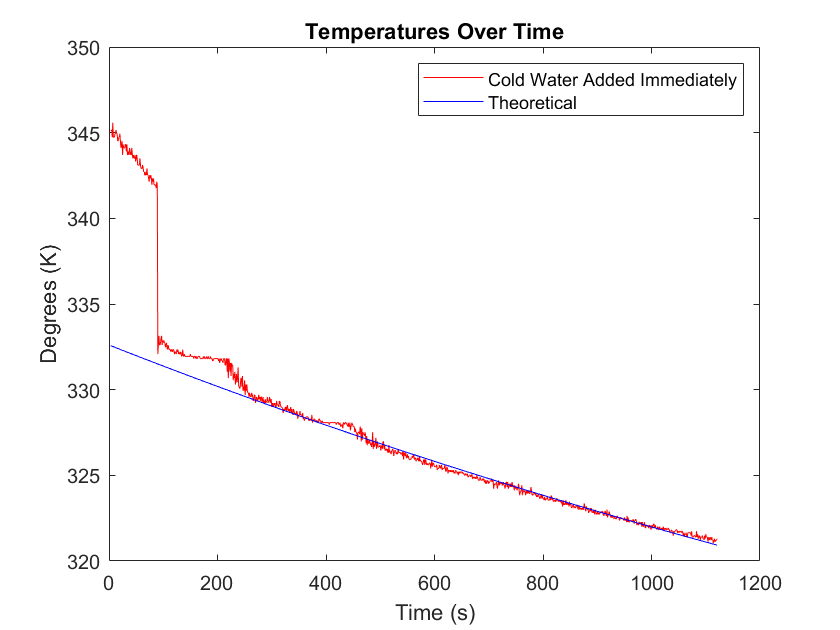


measured_data_fit = 295.15 + (cup_1_temperature(89,1)-295.15)*exp(-cup_1_time/3000);

% Calculate Measured Temperature Curve

plot(cup_1_time,cup_1_temperature, 'r', cup_1_time, measured_data_fit, 'b')
legend('Cold Water Added Immediately','Theoretical')
xlabel('Time (s)'), ylabel('Degrees (K)')
title('Temperatures Over Time')